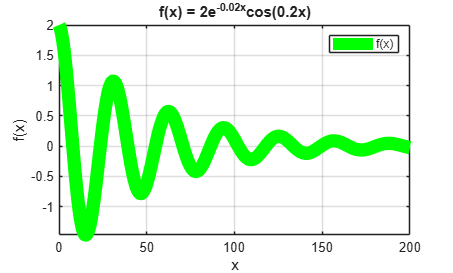

% 1 uzduotis

%a)

x = linspace(0,200,300);

y = 2*exp(-0.02*x).*cos(0.2*x);

figure(1)
plot(x,y,'g','LineWidth',10)

title('f(x) = 2e^{-0.02x}cos(0.2x)')
xlabel('x')
ylabel('f(x)')
legend('f(x)')
grid on

axis([min(x) max(x) min(y) max(y)])

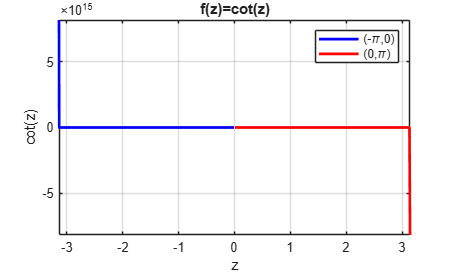


%b)

z1 = linspace(-pi,-0.01,1000);
z2 = linspace(0.01,pi,1000);

f1 = cot(z1);
f2 = cot(z2);

figure(2)
plot(z1,f1,'b','LineWidth',2)
hold on
plot(z2,f2,'r','LineWidth',2)

title('f(z)=cot(z)')
xlabel('z')
ylabel('cot(z)')
legend('(-\pi,0)','(0,\pi)')
grid on

axis([-pi pi min([f1 f2]) max([f1 f2])])

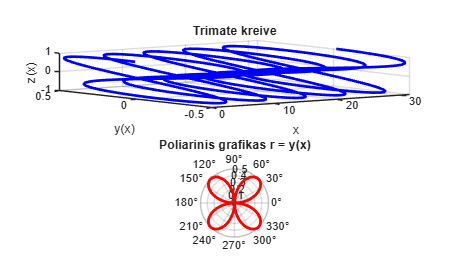

% 2 uzduotis
x = 0:0.1:10*pi;

y = sin(x).*cos(x);
z = cos(x);

figure

% a)
subplot(2,1,1)

plot3(x,y,z,'b','LineWidth',2)

title('Trimate kreive')
xlabel('x')
ylabel('y(x)')
zlabel('z(x)')
grid on

% b)
subplot(2,1,2)

polarplot(x,y,'r','LineWidth',2)

title('Poliarinis grafikas r = y(x)')

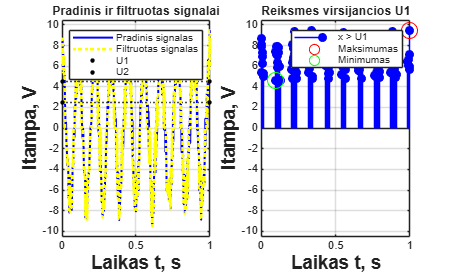

% Papildoma uzduotis
% Duomenys is 2 laboratorinio

A = 7;
f = 9;
sigma = 1.2;
U1 = 4.5;
U2 = 2.5;

t = 0:0.002:1;

s = A*cos(2*pi*f*t);
n = sigma*randn(size(t));

x = s + n;

x_filtruotas = x;
x_filtruotas(abs(x_filtruotas) < U2) = 0;

% Reiksmes virsijancios U1
x_U1 = x;
x_U1(x_U1 <= U1) = NaN;

% Minimali ir maksimali reiksmes
ind = find(x > U1);
[max_reiksme, i_max] = max(x(ind));
[min_reiksme, i_min] = min(x(ind));
max_indeksas = ind(i_max);
min_indeksas = ind(i_min);

figure

% Pirmas grafikas

subplot(1,2,1)

plot(t,x,'b-','LineWidth',1.5)
hold on

plot(t,x_filtruotas,'y:','LineWidth',2)

plot([t(1) t(end)],[U1 U1],'k.','MarkerSize',10)
plot([t(1) t(end)],[U2 U2],'k.','MarkerSize',10)

yline(U1,'k:')
yline(U2,'k:')

title('Pradinis ir filtruotas signalai','FontWeight','bold')
xlabel('Laikas t, s','FontSize',14,'FontWeight','bold')
ylabel('Itampa, V','FontSize',14,'FontWeight','bold')

legend('Pradinis signalas','Filtruotas signalas','U1','U2')
grid on

axis([0 1 min(x)-1 max(x)+1])

% Antras grafikas

subplot(1,2,2)

stem(t,x_U1,'b','filled')
hold on

plot(t(max_indeksas),max_reiksme,'ro','MarkerSize',12)
plot(t(min_indeksas),min_reiksme,'go','MarkerSize',12)

title('Reiksmes virsijancios U1','FontWeight','bold')
xlabel('Laikas t, s','FontSize',14,'FontWeight','bold')
ylabel('Itampa, V','FontSize',14,'FontWeight','bold')

legend('x > U1','Maksimumas','Minimumas')
grid on

axis([0 1 min(x)-1 max(x)+1])